Parameters

fc = 500; %2kHz
fs = 8000;

Text Encoding

text = ['hello world, vicky was in the musical. ' ...
    'Yichen does not wear glasses' ...
    'Yichen smushed matlab'];
text_bin = dec2bin(double(text));
s = size(text_bin);
bin_str = reshape(text_bin.'-'0',1,[]); %create string
header = zeros(1,20);
text_bin = [header,bin_str]; %create string with header and message
text_bin = 2 .* text_bin - 1; % convert from 0,1 to -1,1
bin_str_us = upsample(text_bin, 100); %upsample
pulse = ones(100, 1);
X_I = conv(bin_str_us, pulse);
time = [0:length(X_I)-1]*1/fs;
X = X_I .* cos(2*pi*fc*time);

Transmit Sound

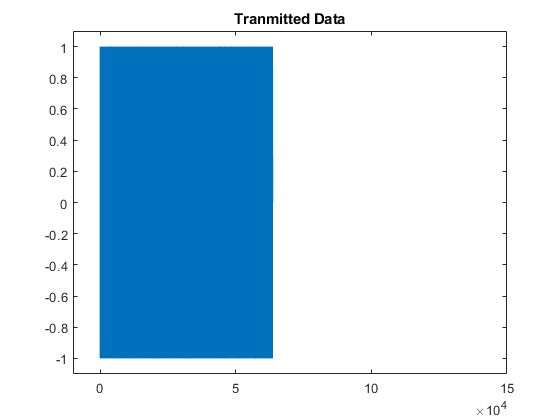

sound(X/4, fs);
% visualize Transmit
figure();
plot(X)
xlim([-1*10^4,15*10^4])
ylim([-1.1,1.1])
title('Tranmitted Data')

Decode Transmitted Signal w/o Noise

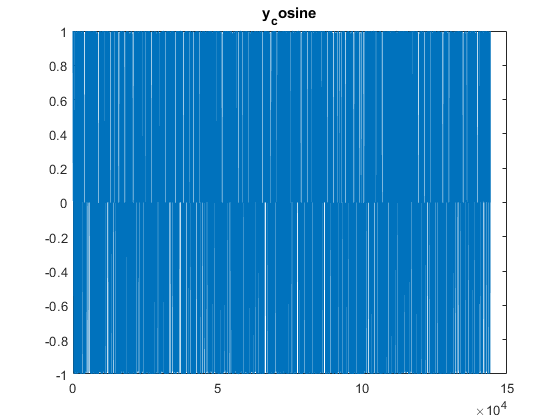

y_received = X;
% cosine and sine
fc = 2000;
fs = 44100;
time = [0:length(y_received)-1]*1/fs;
y_cos = y_received.*cos(2*pi*fc*time);
y_sin = - y_received.*sin(2*pi*fc*time)*1i;
figure();
plot(y_cos)
title('y_cosine')

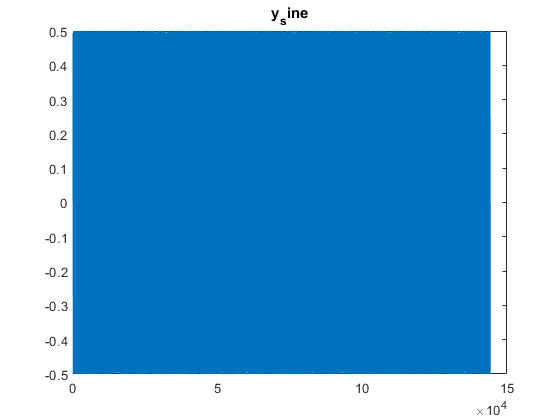

figure();
plot(imag(y_sin))
title('y_sine')

%y_complex = y_cos + y_sin;
y_complex = y_cos + y_sin;
disp("lowpassing..");

lowpassing..


% we are not sure about the parameters for lowpass filter
y_complex = lowpass(y_complex, fc/10, 44.1e3);
disp("done lowpassing");

done lowpassing


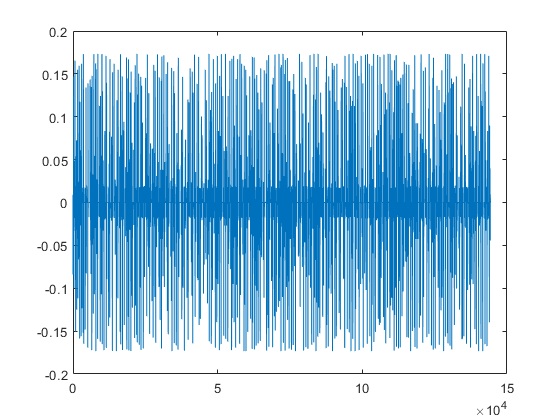

plot(imag(y_complex))

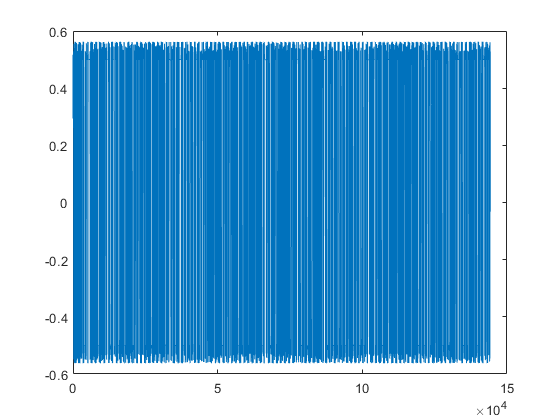

plot(real(y_complex))

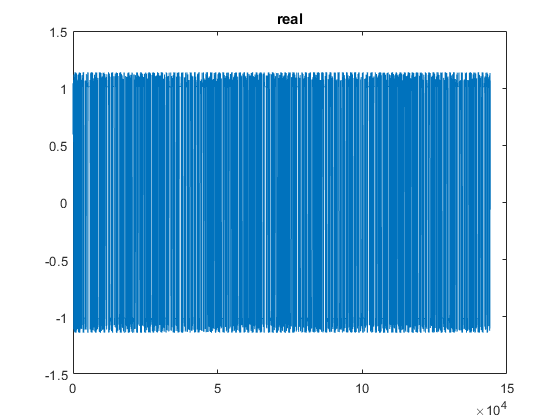

% normalize received signal
y_complex = transpose(y_complex);
y_mag = rms(y_complex);
y_complex = y_complex ./ y_mag;
y_size = size(y_complex);

% initialize all variables
phi = zeros(y_size(1),1);
x_prime = zeros(y_size(1),1);
e = zeros(y_size(1), 1);
d = zeros(y_size(1),1);
k = 1;
%setting the value for alpha and beta
beta = 0.1;
alpha = 0.01;

% loop through k and minize error
while k < y_size(1)
    x_prime(k) = y_complex(k) * exp(1i*phi(k));
    e(k) = -real(x_prime(k)) * imag(x_prime(k));
    d(k) = beta * e(k) + alpha * sum(e(1:k));
    phi(k+1) = phi(k) + d(k);
    while phi(k+1) < -pi
        phi(k+1) = phi(k+1) + 2*pi;
    end
    while phi(k+1) > pi
        phi(k+1) = phi(k+1) - 2*pi;
    end
    k = k + 1;
end
plot(real(x_prime))
title('real')

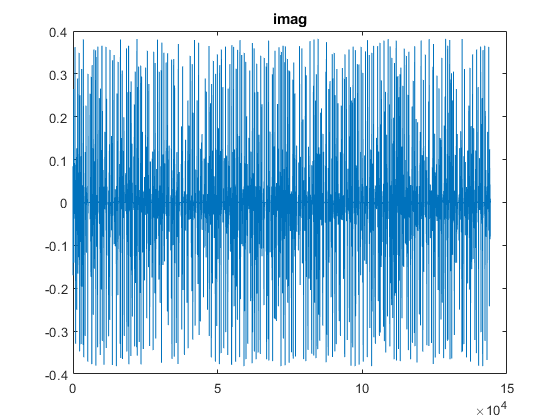

plot(imag(x_prime))
title('imag')

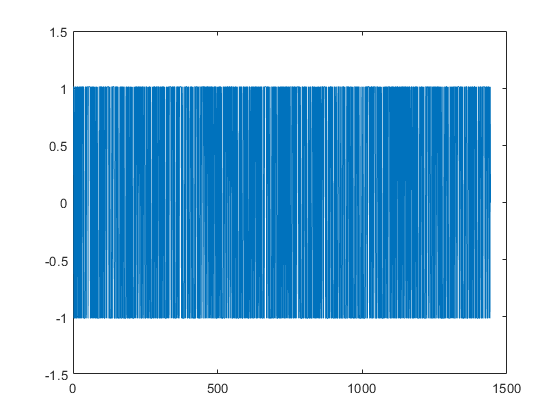


x_res = downsample(real(x_prime(50:end)), 100);
plot(x_res);

% converting to 1 and 0
for i=1:size(x_res)
    if x_res(i) > 0
        x_res(i) = 1;
    end
    if x_res(i) < 0
        x_res(i) = 0;
    end
end

% break down long string into individual character
full_str = sprintf('%d',x_res');
% diff is added here to correct for possible offset
diff = 0;
full_str_len = floor(length(full_str)/7)*7;
full_str = full_str(1+diff:full_str_len+diff);
str_size = idivide(int16(strlength(full_str)),int16(7));
ascii_list = strings(str_size, 1);
for i = 0:str_size-1
    ascii_list(i+1) = full_str(i*7+1:(i+1)*7);
end
result = "";
for i = 1:str_size
    result = append(result, char(bin2dec(ascii_list(i))));
end
result

result = "hello world, vicky was in the musical. Yichen does not wear glassesYichen smushed matlabturns out implementation is hardVicky is happy she is a software engineeringYichen is suprised by Vickys career choise"